
%Starting/ending (day)
t0 = 0; 
tF = 50;

%timestep
h = 1/24;
time = t0:h:tF;

%Initial value of biomass at time t0 (tons)
x0 = 20;

%The maximum sustainable fish biomass.
%xx = 99999;

%the natural growth function
syms x real
g =@(x) 0.05*x;
sym_derr = diff(g(x));
derr_g = matlabFunction(sym_derr);



%the rate of fishing effort at time t(tons/time)
u0 = sin(time(1:end-1)); %ones(1,1 + (tF-t0)/h).*5;
%u0 = zeros(1,length(time(1:end-1)));
du0 = cos(time(1:end-1));

%the catchability coefficient(1/tons)
q = 0.0001;

%the discount rate(no unit)
rho = 0.1;

%the unit price of landed fish(money/tons)
p = 3000;

%the unit cost of (money/tons)
c = 1;

%derivative of x w.r.t. t
f =@(t,x,u) g(x) - q.*u.*x;

%[th, uh] = explicit_euler(u0, f, t0, tF, x0,  h);


%plot(th, jj(th), "g");
%plot(th,uh,"-ob");




% j_hat = Jhat(u0,th,uh,h,rho,c,p,q);
% [Jh] = cost(u0, f, t0, tF, x0, h, rho,c,p,q);
lambda_N = 0;
% lambdas = lambda_array(u0,th,uh,h,rho,p,q,lambda_N, derr_g());
bheta = 1/2;
% gr_j_hat = gradient_j_hat(u0, th, uh, h, rho, c, p, q, lambdas, bheta);
% [gr_Jh] = gr_cost(u0, f, t0, tF, x0, h, rho,c,p,q, lambda_N, derr_g(), bheta);
% epsilons = [1, 0.1, 0.01, 0.001];
% values = zeros(1,length(epsilons));
% for i = 1:length(epsilons)
%     Jh_norm = cost(u0, f, t0, tF, x0, h, rho,c,p,q);
%     Jh_eps = cost(u0+epsilons(i).*du0, f, t0, tF, x0, h, rho,c,p,q);
%     gr_Jh = gr_cost(u0, f, t0, tF, x0, h, rho,c,p,q, lambda_N, derr_g(), bheta);
%     t_du0 = transpose(du0);
%     value = ((Jh_eps-Jh_norm)/epsilons(i)) - (gr_Jh*t_du0);
%     values(1,i) = value;
% end
% loglog(epsilons,values); hold on; loglog(epsilons,epsilons)
    



data.J =@(u) cost(u, f, t0, tF, x0, h, rho,c,p,q);
data.dJ = @(u) gr_cost(u, f, t0, tF, x0, h, rho,c,p,q, lambda_N, derr_g(), bheta);

data.linesearch = @(data,u,d) armijo_back(data,u,d,1e-4,50); 
%u0 = u0;
tol = 1e-6;
[u,opt,it,um,optm] = descentmethod(data,tol,50,u0);

it=   1 J(u)= 2.304332e+15 |dJ(u)|= 1.733931e+01
it=   2 J(u)= 2.304362e+15 |dJ(u)|= 1.731219e+01
it=   3 J(u)= 2.304391e+15 |dJ(u)|= 1.728509e+01
it=   4 J(u)= 2.304420e+15 |dJ(u)|= 1.725801e+01
it=   5 J(u)= 2.304450e+15 |dJ(u)|= 1.723095e+01
it=   6 J(u)= 2.304479e+15 |dJ(u)|= 1.720390e+01
it=   7 J(u)= 2.304509e+15 |dJ(u)|= 1.717687e+01
it=   8 J(u)= 2.304538e+15 |dJ(u)|= 1.714985e+01
it=   9 J(u)= 2.304567e+15 |dJ(u)|= 1.712285e+01
it=  10 J(u)= 2.304596e+15 |dJ(u)|= 1.709587e+01
it=  11 J(u)= 2.304626e+15 |dJ(u)|= 1.706891e+01
it=  12 J(u)= 2.304655e+15 |dJ(u)|= 1.704196e+01
it=  13 J(u)= 2.304684e+15 |dJ(u)|= 1.701503e+01
it=  14 J(u)= 2.304713e+15 |dJ(u)|= 1.698811e+01
it=  15 J(u)= 2.304742e+15 |dJ(u)|= 1.696122e+01
it=  16 J(u)= 2.304771e+15 |dJ(u)|= 1.693433e+01
it=  17 J(u)= 2.304800e+15 |dJ(u)|= 1.690747e+01
it=  18 J(u)= 2.304829e+15 |dJ(u)|= 1.688062e+01
it=  19 J(u)= 2.304858e+15 |dJ(u)|= 1.685379e+01
it=  20 J(u)= 2.304887e+15 |dJ(u)|= 1.682698e+01
it=  21 J(u)= 2.3049

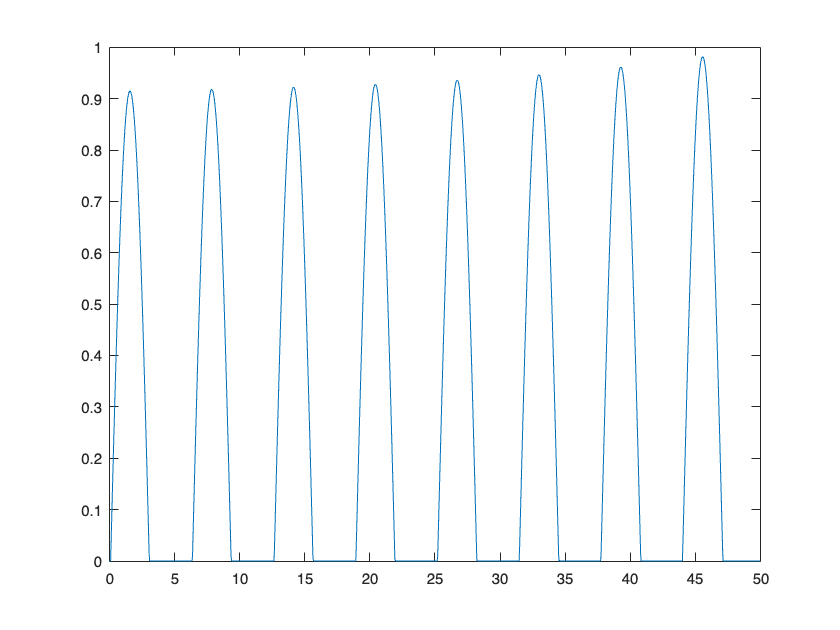

u;
s = time(1:end-1);
s;
plot(s,u)

[th, uh] = explicit_euler(u, f, t0, tF, x0,  h);
%%%%%% !!!!!!!! HOW TO CONSTRAINT THE X -> POPULATION (if upper bound of u is 500, uh(x) gonna be negative)
uh

uh =    20.0000   20.0417   20.0834   20.1253   20.1672   20.2092   20.2513   20.2935   20.3357   20.3781   20.4205   20.4630   20.5056   20.5483   20.5911   20.6339   20.6769   20.7199   20.7630   20.8062   20.8495   20.8929   20.9364   20.9799   21.0236   21.0673   21.1111   21.1550   21.1990   21.2431   21.2873   21.3316   21.3759   21.4204   21.4649   21.5096   21.5543   21.5991   21.6440   21.6891   21.7342   21.7794   21.8247   21.8700   21.9155   21.9611   22.0068   22.0525   22.0984   22.1444


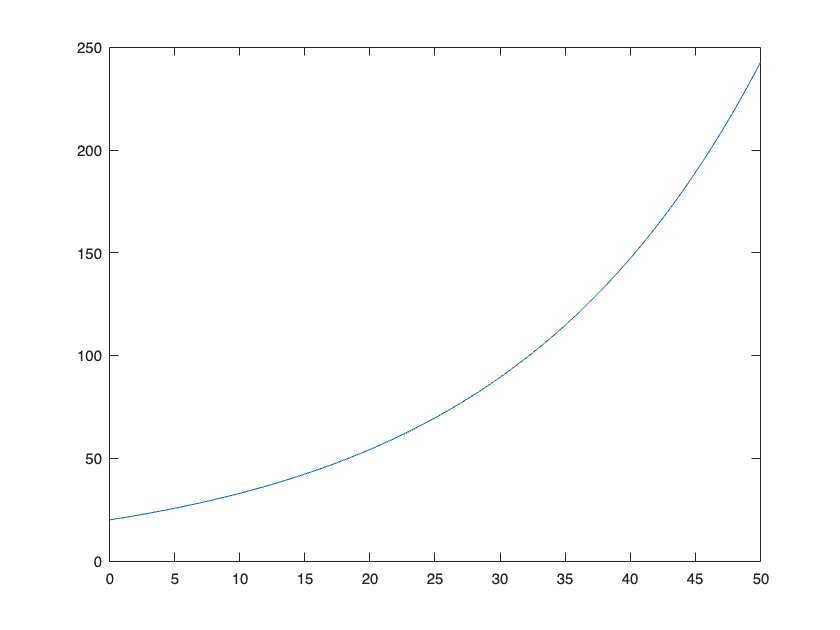

plot(th,uh)



% N = 100;
% xp = linspace(1,4,N);
% yp = linspace(1,3,N);
% [X,Y] = meshgrid(xp,yp);
% JJ = cost(u, f, t0, tF, x0, h, rho,c,p,q);
% contourf(X,Y,JJ,20); hold on;
% colormap(hsv);
% colorbar; plot(um(1,:),um(2,:),'*−k','MarkerSize',5,'LineWidth',2);














% [th, uh] = runge_method(f, t0, tF, x0,  h);
% jj =@(t) exp(-t*rho).*(p.*q.*uh-c).*u(t);
% 
% %plot(th, jj(th), "k");
% plot(th,uh,"-ob");
% 
% [th, uh] = heun_method(f, t0, tF, x0,  h);
% jj =@(t) exp(-t*rho).*(p.*q.*uh-c).*u(t);
% 
% %plot(th, jj(th), "k");
% plot(th,uh,"-ob");
% 
% [th, uh] = rk4_method(f, t0, tF, x0,  h);
% jj =@(t) exp(-t*rho).*(p.*q.*uh-c).*u(t);
% 
% %plot(th, jj(th), "k");
% plot(th,uh,"-ob");
% 
% a =@(t) 1-q*u(t);
% b =@(t) 0;
% [th, uh] = implicit_euler(a, b, t0, tF, x0,  h);
% jj =@(t) exp(-t*rho).*(p.*q.*uh-c).*u(t);
% 
% %plot(th, jj(th), "g");
% plot(th,uh,"-ob")
% [th, uh] = crank_nicolson(a, b, t0, tF, x0, h);
% jj =@(t) exp(-t*rho).*(p.*q.*uh-c).*u(t);
% 
% %plot(th, jj(th), "b");
% plot(th,uh,"-g");
